# Lab 3: OFDM Modulation

Kristtiya Guerra and Utsav Gupta

clc; clear all; close all;

#### Parameters

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16;    % Sets of Training Data 
N_XData = 84;       % Sets of True Data 
Bits_per_set = 64;  % Bits per set of data
size_training_data = Bits_per_set*N_Training;       % Size of Training Data - 16 sets of 64 bits: 1024
size_X = Bits_per_set*N_XData;                      % Size of data - 84 sets of 64 bits: 5376 bits

#### Generating Random Data to Transmit

Create Data and Training Data

range = [-1 1]; % List of wanted values: 
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

**Schmidl-Cox Preamble**

pre = randi([0,1],1,64); % 64 columns 1 row
pre(pre == 0) = -1; %Changes all zeroes to -1
pre = ifft(pre); %Move to time domain (64 point ifft)
preamble = [pre,pre,pre]; %196 columns, 1 row

#### IDFT - Takes inverse discrete fourier tranform of data

Add Cyclic Prefix after each ifft

%IFFT of each individual set of 64
%Add prefix 
Len_CP = 16;
n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data
tx_data = zeros(8000,1);


for x_time = 1:1:5
    Data_x_n = message(1 + 64*(x_time-1):x_time*64); %Extracts data set n_data - 64 bits
    Data_X_n = ifft(Data_x_n);  %Obtains the ifft of the data: Frequency to Time- 64 bits
    test_recovery = fft(Data_X_n);
    cyclic_prefix = Data_X_n(49:end); % Obtains the last 16 bits of the data
    recoverprefix = fft(cyclic_prefix);
    Prefix_w_data = [cyclic_prefix ; Data_X_n];%Concatonate the cyclic prefix to the data set - 80 bits
    test_recovery1 = fft(Prefix_w_data); %Time to frequency
    test_woutpre = fft(Prefix_w_data(17:end));
    tx_data(1+80*(x_time-1):80*(x_time)) = Prefix_w_data;%Append data into the tx_data vector
end


#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel(tx_data);

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index); %Should be 9

%Remove Extra Data
rx_data = rx_data(shift1_train:end); %Should be 8000 bits

#### Schmidl-Cox

headers = 64*3; %64 is lenght of sample
lts_rx = rx(idx:idx+headers)
f_sum = 0;
for i = 1:1:64
    f_sum = f_sum + angle(lts_rx(96+i)/lts_rx(32+i));
end
f_delta = f_sum)/(64*64);

rx_phase_corr = zeros(length(rx,1));

for j=1:1:length(rx(idx:end))
    rx_phase_corr(idx+j-1)=rx(idx+j-1)/exp(1i*f_delta*(j-1));
end

#### Channel Estimation: Estimating channel for each set of 64 bits using the Training Data

H_est = zeros(64,1);

%Obtain Training Data
Size_PC = 16;
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_set; %1280 Bits
Training_data_xm= rx_data(1:Size_Training_PC)

Training_data_xm =   -0.0413 + 0.0115i
   0.2178 - 0.0655i
  -0.0352 + 0.0491i
   0.0624 - 0.0945i
   0.0676 - 0.1747i
  -0.0672 + 0.0270i
   0.0804 + 0.2019i
   0.0649 - 0.0366i
   0.0533 - 0.0888i
  -0.0375 + 0.0007i



Cleaned_Training_Data = zeros(N_Training*Bits_per_set,1);

%removing cyclic prefix
for V = 1:1:N_Training
    Set = Training_data_xm(1 + 80*(V-1):80*V);
    remove_prefix = Set(17:end);
    dat = (fftshift(fft(remove_prefix))); %Move data to the frequency domain
    Cleaned_Training_Data(1+64*(V-1):64*V) = dat;
end


for G = 1:1:64  
    Data_N = Cleaned_Training_Data(G:64:end); %Obtain N data from each set of 16- array dim 16x1
    OriginalChannel = message(G);
    Channel_estimate = Data_N/OriginalChannel; % Estimate the channel
    H_est(G) = mean(Channel_estimate);
end

Decode

Y_m = zeros(length(message),1);

for V = 1:1:n_data
    Set = rx_data(1 + 80*(V-1):80*V) %Extract n_data set of 80 bits - 80 bits
    remove_prefix = Set(17:end); %Remove Cyclic prefix and produce true data - 64 bits
    Y = fftshift(fft(remove_prefix)); %Move data to frequency domain - Move data to the frequency domain
    X_est=Y./H_est;
    Y_m(1 + 64*(V-1):64*V) = X_est;
end

Set =   -0.0413 + 0.0115i
   0.2178 - 0.0655i
  -0.0352 + 0.0491i
   0.0624 - 0.0945i
   0.0676 - 0.1747i
  -0.0672 + 0.0270i
   0.0804 + 0.2019i
   0.0649 - 0.0366i
   0.0533 - 0.0888i
  -0.0375 + 0.0007i


Set =   -0.0471 - 0.0382i
  -0.0380 + 0.0678i
   0.0417 - 0.0709i
  -0.1461 - 0.0604i
   0.0507 + 0.0514i
   0.0918 - 0.0836i
  -0.0071 + 0.0563i
   0.1508 - 0.0432i
  -0.0005 - 0.1235i
  -0.0317 - 0.0651i


Set =   -0.0778 - 0.0157i
   0.0329 + 0.0375i
  -0.0392 + 0.0175i
   0.0608 - 0.0497i
  -0.0934 + 0.1080i
  -0.0990 + 0.0856i
   0.1877 + 0.0517i
   0.0552 - 0.1120i
  -0.0582 - 0.0597i
   0.0473 + 0.0586i


Set =   -0.0252 + 0.1149i
   0.0223 - 0.0939i
   0.0028 - 0.0240i
  -0.1163 + 0.2133i
  -0.0875 + 0.0003i
   0.1484 - 0.0360i
   0.0517 - 0.0280i
   0.1571 + 0.0960i
   0.0809 - 0.0737i
  -0.0223 - 0.0120i


Set =    0.1559 - 0.0676i
   0.1700 + 0.0389i
  -0.1332 + 0.1123i
   0.0993 - 0.0752i
   0.0402 - 0.0454i
  -0.2259 + 0.0634i
  -0.0183 + 0.0737i
  -0.0469 + 0.0438i
   0.1420 - 0.0991i
   0.0655 - 0.0241i


Set =   -0.0419 + 0.0783i
  -0.0167 + 0.0154i
   0.0112 - 0.0083i
  -0.0099 + 0.0076i
   0.0066 - 0.0054i
  -0.0032 + 0.0023i
   0.0012 - 0.0028i
  -0.0002 + 0.0011i
   0.0013 - 0.0006i
  -0.0002 - 0.0004i


Set =   -0.0001 - 0.0009i
   0.0001 + 0.0013i
  -0.0012 + 0.0002i
   0.0006 + 0.0004i
  -0.0001 - 0.0008i
   0.0000 - 0.0003i
   0.0006 - 0.0013i
  -0.0002 - 0.0010i
   0.0003 - 0.0010i
  -0.0005 - 0.0012i


Set =   -0.0006 - 0.0005i
  -0.0010 - 0.0002i
   0.0001 - 0.0010i
   0.0005 - 0.0004i
   0.0005 + 0.0008i
  -0.0001 + 0.0003i
   0.0011 - 0.0006i
   0.0001 + 0.0003i
  -0.0003 - 0.0005i
   0.0001 - 0.0014i


Set =   -0.0004 - 0.0005i
   0.0005 + 0.0010i
  -0.0003 + 0.0009i
   0.0003 + 0.0005i
  -0.0001 - 0.0010i
  -0.0003 - 0.0003i
   0.0003 + 0.0003i
   0.0002 + 0.0002i
  -0.0013 - 0.0004i
  -0.0002 + 0.0010i


Set =    0.0015 + 0.0002i
  -0.0006 - 0.0002i
  -0.0002 - 0.0003i
  -0.0008 - 0.0002i
  -0.0005 + 0.0008i
   0.0006 + 0.0005i
   0.0005 - 0.0005i
  -0.0006 - 0.0005i
   0.0001 - 0.0011i
  -0.0003 + 0.0007i


Set =   -0.0011 + 0.0005i
  -0.0005 - 0.0000i
  -0.0004 - 0.0007i
   0.0009 - 0.0008i
   0.0001 - 0.0006i
   0.0013 - 0.0005i
   0.0003 - 0.0001i
   0.0002 - 0.0000i
  -0.0001 - 0.0004i
  -0.0006 - 0.0001i


Set =    0.0003 - 0.0005i
  -0.0014 - 0.0002i
  -0.0010 - 0.0004i
  -0.0005 + 0.0001i
   0.0001 - 0.0004i
   0.0002 + 0.0002i
   0.0016 - 0.0005i
  -0.0011 + 0.0004i
  -0.0011 - 0.0001i
  -0.0002 - 0.0013i


Set =   -0.0005 + 0.0008i
  -0.0004 + 0.0004i
  -0.0011 - 0.0001i
   0.0007 - 0.0002i
   0.0000 - 0.0007i
  -0.0001 + 0.0006i
   0.0001 + 0.0005i
  -0.0005 - 0.0001i
  -0.0002 + 0.0002i
   0.0006 + 0.0002i


Set =    0.0006 - 0.0003i
   0.0003 - 0.0006i
  -0.0008 + 0.0007i
   0.0000 + 0.0014i
   0.0004 - 0.0001i
  -0.0004 - 0.0005i
  -0.0004 + 0.0002i
   0.0002 - 0.0006i
  -0.0007 - 0.0005i
  -0.0004 + 0.0004i


Set =    0.0006 + 0.0013i
   0.0002 + 0.0010i
   0.0009 - 0.0002i
   0.0010 + 0.0008i
  -0.0004 - 0.0000i
   0.0000 - 0.0001i
   0.0004 - 0.0007i
   0.0008 - 0.0002i
   0.0001 - 0.0005i
  -0.0003 - 0.0001i


Set =   -0.0009 - 0.0001i
   0.0004 - 0.0004i
  -0.0002 + 0.0003i
   0.0004 + 0.0005i
   0.0008 + 0.0002i
  -0.0002 + 0.0003i
   0.0005 + 0.0003i
   0.0019 - 0.0007i
  -0.0002 + 0.0005i
   0.0003 - 0.0006i


Set =   -0.0001 - 0.0007i
   0.0001 + 0.0011i
   0.0014 - 0.0011i
   0.0009 + 0.0002i
  -0.0003 + 0.0004i
  -0.0012 + 0.0001i
  -0.0003 - 0.0006i
   0.0001 + 0.0002i
  -0.0013 - 0.0001i
   0.0008 + 0.0001i


Set =    0.0007 - 0.0008i
  -0.0009 - 0.0004i
   0.0003 + 0.0005i
   0.0005 - 0.0005i
   0.0003 + 0.0005i
  -0.0005 - 0.0005i
   0.0003 + 0.0012i
  -0.0006 + 0.0007i
   0.0002 - 0.0007i
  -0.0004 + 0.0005i


Set =    0.0002 + 0.0007i
   0.0007 + 0.0013i
   0.0003 + 0.0006i
  -0.0002 + 0.0004i
  -0.0002 - 0.0008i
  -0.0016 + 0.0004i
  -0.0006 + 0.0010i
  -0.0003 + 0.0006i
  -0.0004 + 0.0001i
   0.0005 - 0.0002i


Set =    0.0010 + 0.0002i
  -0.0012 - 0.0003i
   0.0007 - 0.0003i
  -0.0004 + 0.0012i
  -0.0008 + 0.0009i
  -0.0004 - 0.0007i
  -0.0003 + 0.0004i
   0.0002 - 0.0003i
  -0.0001 - 0.0002i
  -0.0009 - 0.0005i


Set =   -0.0007 + 0.0002i
   0.0006 + 0.0016i
   0.0001 + 0.0002i
  -0.0005 - 0.0002i
  -0.0001 - 0.0014i
  -0.0001 + 0.0009i
   0.0000 + 0.0003i
   0.0001 - 0.0002i
  -0.0001 + 0.0011i
  -0.0003 + 0.0011i


Set =    0.0003 + 0.0008i
  -0.0006 - 0.0002i
   0.0001 + 0.0008i
   0.0011 + 0.0007i
  -0.0004 - 0.0003i
   0.0001 + 0.0012i
   0.0001 + 0.0007i
  -0.0006 + 0.0002i
   0.0002 - 0.0003i
   0.0001 + 0.0002i


Set =    0.0006 + 0.0003i
  -0.0006 - 0.0002i
   0.0000 - 0.0005i
  -0.0002 - 0.0003i
  -0.0005 + 0.0015i
   0.0001 - 0.0001i
  -0.0009 - 0.0003i
  -0.0011 - 0.0004i
  -0.0009 + 0.0003i
  -0.0005 - 0.0002i


Set =   -0.0005 - 0.0001i
   0.0012 - 0.0005i
   0.0006 - 0.0002i
   0.0004 - 0.0004i
   0.0000 - 0.0003i
  -0.0004 + 0.0005i
   0.0008 - 0.0000i
   0.0007 - 0.0004i
  -0.0011 - 0.0002i
  -0.0007 + 0.0004i


Set =    0.0003 - 0.0007i
  -0.0009 + 0.0007i
   0.0003 + 0.0003i
   0.0001 + 0.0007i
   0.0007 - 0.0004i
   0.0001 - 0.0013i
  -0.0006 - 0.0002i
  -0.0006 - 0.0002i
  -0.0008 + 0.0002i
   0.0002 + 0.0007i


Set =   -0.0005 - 0.0008i
   0.0000 - 0.0002i
   0.0009 + 0.0002i
  -0.0006 + 0.0002i
   0.0008 + 0.0000i
  -0.0011 - 0.0011i
  -0.0001 - 0.0002i
   0.0009 + 0.0005i
   0.0004 + 0.0013i
  -0.0000 + 0.0005i


Set =    0.0002 - 0.0005i
  -0.0002 + 0.0001i
   0.0004 + 0.0003i
  -0.0009 - 0.0001i
   0.0007 + 0.0010i
   0.0002 + 0.0006i
   0.0002 + 0.0008i
  -0.0008 + 0.0007i
  -0.0004 - 0.0002i
   0.0001 - 0.0018i


Set =    0.0009 + 0.0011i
  -0.0001 - 0.0001i
  -0.0002 - 0.0008i
  -0.0005 + 0.0007i
   0.0011 + 0.0004i
   0.0015 - 0.0007i
   0.0007 - 0.0010i
  -0.0004 + 0.0003i
  -0.0008 + 0.0002i
  -0.0006 + 0.0001i


Set =   -0.0005 - 0.0005i
  -0.0004 - 0.0002i
   0.0011 + 0.0005i
   0.0016 + 0.0003i
  -0.0005 + 0.0005i
  -0.0012 + 0.0013i
   0.0003 - 0.0008i
  -0.0005 + 0.0001i
  -0.0000 - 0.0004i
  -0.0001 - 0.0002i


Set =   -0.0015 + 0.0000i
   0.0011 - 0.0004i
  -0.0005 + 0.0005i
   0.0002 - 0.0008i
  -0.0010 - 0.0000i
  -0.0003 - 0.0006i
   0.0006 + 0.0001i
  -0.0008 - 0.0001i
   0.0003 - 0.0008i
  -0.0008 + 0.0001i


Set =    0.0007 - 0.0001i
  -0.0002 - 0.0003i
  -0.0004 - 0.0006i
   0.0009 + 0.0010i
   0.0004 + 0.0001i
  -0.0004 - 0.0001i
   0.0009 + 0.0013i
  -0.0002 + 0.0002i
  -0.0000 - 0.0000i
  -0.0000 - 0.0001i


Set =    0.0009 + 0.0001i
   0.0003 + 0.0013i
   0.0003 - 0.0010i
  -0.0001 + 0.0009i
  -0.0005 + 0.0009i
  -0.0003 + 0.0007i
   0.0003 + 0.0002i
  -0.0006 + 0.0007i
  -0.0000 - 0.0012i
  -0.0005 - 0.0004i


Set =   -0.0000 + 0.0002i
  -0.0002 - 0.0005i
   0.0001 - 0.0001i
   0.0001 + 0.0001i
  -0.0005 + 0.0001i
   0.0001 + 0.0008i
  -0.0004 + 0.0008i
  -0.0007 + 0.0006i
   0.0001 - 0.0000i
   0.0006 - 0.0001i


Set =   -0.0004 + 0.0007i
   0.0000 - 0.0008i
  -0.0006 - 0.0012i
   0.0011 + 0.0003i
   0.0001 - 0.0003i
  -0.0002 + 0.0011i
  -0.0008 - 0.0007i
   0.0002 + 0.0000i
  -0.0007 + 0.0002i
  -0.0007 - 0.0000i


Set =    0.0003 - 0.0001i
   0.0010 + 0.0009i
   0.0002 - 0.0007i
   0.0000 - 0.0002i
   0.0000 - 0.0009i
   0.0002 - 0.0011i
   0.0007 + 0.0008i
   0.0002 - 0.0002i
   0.0008 + 0.0000i
  -0.0001 - 0.0004i


Set =    0.0004 + 0.0002i
   0.0002 - 0.0006i
  -0.0001 - 0.0006i
  -0.0003 - 0.0004i
   0.0004 - 0.0004i
   0.0001 - 0.0010i
  -0.0005 - 0.0000i
   0.0000 - 0.0009i
  -0.0006 + 0.0001i
  -0.0005 + 0.0003i


Set =   -0.0006 - 0.0006i
  -0.0001 - 0.0002i
   0.0003 + 0.0008i
   0.0004 + 0.0008i
  -0.0002 + 0.0002i
  -0.0001 + 0.0001i
   0.0004 - 0.0005i
   0.0005 - 0.0007i
   0.0008 - 0.0004i
  -0.0012 + 0.0007i


Set =    0.0004 - 0.0001i
   0.0004 - 0.0010i
   0.0007 - 0.0003i
   0.0004 + 0.0013i
   0.0005 + 0.0003i
  -0.0002 + 0.0003i
   0.0014 + 0.0011i
   0.0002 - 0.0006i
   0.0003 - 0.0003i
   0.0008 - 0.0007i


Set =   -0.0000 - 0.0003i
  -0.0000 - 0.0006i
   0.0004 - 0.0003i
   0.0000 + 0.0015i
   0.0004 + 0.0004i
   0.0011 + 0.0002i
   0.0004 + 0.0001i
  -0.0001 - 0.0002i
  -0.0005 + 0.0001i
   0.0012 + 0.0004i


Set =   -0.0016 + 0.0005i
  -0.0008 - 0.0003i
   0.0008 + 0.0013i
   0.0004 - 0.0005i
   0.0001 - 0.0002i
   0.0005 + 0.0006i
  -0.0009 - 0.0014i
  -0.0001 - 0.0007i
  -0.0002 + 0.0001i
   0.0005 + 0.0003i


Set =   -0.0001 - 0.0006i
   0.0001 - 0.0002i
   0.0001 + 0.0001i
   0.0011 + 0.0003i
   0.0001 - 0.0002i
   0.0010 - 0.0012i
   0.0005 - 0.0006i
   0.0005 + 0.0001i
  -0.0009 - 0.0001i
   0.0005 + 0.0010i


Set =    0.0012 + 0.0009i
  -0.0002 + 0.0002i
   0.0008 + 0.0007i
   0.0008 + 0.0001i
  -0.0003 - 0.0001i
   0.0004 - 0.0004i
   0.0006 + 0.0005i
   0.0010 + 0.0002i
  -0.0008 - 0.0007i
  -0.0005 + 0.0004i


Set =   -0.0004 - 0.0012i
  -0.0002 + 0.0002i
   0.0006 + 0.0003i
  -0.0008 - 0.0014i
   0.0005 + 0.0005i
   0.0005 + 0.0008i
   0.0003 + 0.0005i
  -0.0004 + 0.0011i
  -0.0007 + 0.0004i
   0.0006 - 0.0013i


Set =    0.0002 - 0.0001i
   0.0005 + 0.0009i
  -0.0003 - 0.0002i
   0.0010 - 0.0001i
  -0.0002 - 0.0011i
   0.0003 + 0.0002i
  -0.0003 + 0.0001i
   0.0011 + 0.0004i
  -0.0003 - 0.0005i
   0.0006 + 0.0009i


Set =    0.0010 + 0.0007i
  -0.0000 + 0.0019i
  -0.0002 - 0.0005i
  -0.0005 + 0.0001i
   0.0010 - 0.0019i
  -0.0010 - 0.0007i
  -0.0006 - 0.0004i
  -0.0003 + 0.0006i
  -0.0007 - 0.0003i
  -0.0008 + 0.0001i


Set =    0.0007 + 0.0008i
   0.0013 + 0.0004i
   0.0005 - 0.0005i
   0.0010 - 0.0003i
   0.0010 + 0.0003i
   0.0004 + 0.0002i
  -0.0003 - 0.0018i
   0.0006 - 0.0013i
   0.0002 - 0.0003i
  -0.0007 + 0.0008i


Set =    0.0008 + 0.0005i
  -0.0001 - 0.0002i
   0.0008 - 0.0013i
  -0.0002 + 0.0004i
  -0.0004 - 0.0007i
  -0.0008 + 0.0003i
   0.0007 - 0.0004i
  -0.0008 + 0.0007i
  -0.0002 - 0.0010i
  -0.0005 - 0.0004i


Set =   -0.0006 - 0.0004i
   0.0000 - 0.0005i
   0.0001 - 0.0010i
  -0.0001 + 0.0003i
   0.0005 + 0.0001i
  -0.0002 - 0.0002i
   0.0002 - 0.0000i
  -0.0006 - 0.0003i
  -0.0006 + 0.0004i
  -0.0002 + 0.0014i


Set =    0.0006 + 0.0001i
   0.0010 - 0.0002i
  -0.0001 - 0.0009i
  -0.0005 + 0.0002i
   0.0002 + 0.0004i
  -0.0007 + 0.0004i
   0.0006 + 0.0004i
  -0.0006 + 0.0006i
  -0.0004 - 0.0005i
  -0.0013 + 0.0004i


Set =    0.0004 + 0.0011i
   0.0008 + 0.0009i
   0.0006 + 0.0004i
  -0.0007 - 0.0012i
  -0.0002 - 0.0003i
  -0.0010 + 0.0015i
   0.0004 + 0.0005i
   0.0012 - 0.0005i
   0.0010 - 0.0004i
   0.0006 - 0.0002i


Set = 80×1
  -0.0008 + 0.0004i
   0.0006 - 0.0006i
  -0.0001 - 0.0002i
  -0.0001 + 0.0001i
  -0.0004 + 0.0001i
   0.0004 + 0.0007i
  -0.0001 - 0.0010i
  -0.0007 + 0.0008i
  -0.0002 + 0.0009i
  -0.0000 + 0.0003i


Set = 80×1
  -0.0011 + 0.0013i
   0.0001 + 0.0007i
   0.0012 + 0.0005i
   0.0006 + 0.0003i
  -0.0001 - 0.0006i
  -0.0003 + 0.0001i
  -0.0002 - 0.0002i
   0.0002 + 0.0003i
   0.0001 - 0.0004i
  -0.0006 + 0.0016i


Set = 80×1
   0.0002 + 0.0004i
  -0.0007 + 0.0010i
   0.0002 - 0.0014i
   0.0007 + 0.0002i
  -0.0000 - 0.0003i
   0.0008 - 0.0009i
  -0.0002 - 0.0002i
   0.0007 - 0.0001i
  -0.0009 + 0.0014i
   0.0000 - 0.0009i


Set = 80×1
  -0.0013 + 0.0018i
   0.0015 + 0.0000i
   0.0005 - 0.0006i
  -0.0014 + 0.0001i
  -0.0001 - 0.0009i
   0.0006 - 0.0005i
  -0.0004 - 0.0003i
   0.0005 + 0.0000i
  -0.0007 + 0.0008i
   0.0001 + 0.0001i


Set = 80×1
  -0.0021 - 0.0011i
   0.0012 + 0.0009i
  -0.0002 + 0.0004i
   0.0002 + 0.0009i
  -0.0003 + 0.0007i
   0.0001 - 0.0008i
  -0.0002 - 0.0001i
  -0.0000 - 0.0003i
  -0.0003 - 0.0009i
  -0.0007 + 0.0010i


Set = 80×1
   0.0002 - 0.0011i
  -0.0003 + 0.0001i
  -0.0001 + 0.0000i
  -0.0011 + 0.0002i
   0.0005 + 0.0004i
   0.0001 - 0.0002i
   0.0007 + 0.0007i
   0.0004 - 0.0003i
  -0.0005 - 0.0008i
  -0.0008 - 0.0003i


Set = 80×1
  -0.0000 - 0.0009i
  -0.0005 + 0.0002i
  -0.0003 + 0.0007i
  -0.0004 - 0.0005i
  -0.0007 - 0.0002i
   0.0008 + 0.0009i
  -0.0013 + 0.0005i
  -0.0001 - 0.0002i
   0.0001 - 0.0003i
   0.0001 + 0.0003i


Set = 80×1
   0.0003 + 0.0001i
  -0.0006 + 0.0006i
   0.0005 - 0.0008i
   0.0001 - 0.0003i
  -0.0003 - 0.0015i
  -0.0003 + 0.0008i
  -0.0013 + 0.0006i
  -0.0001 - 0.0003i
   0.0003 - 0.0003i
   0.0002 + 0.0014i


Set = 80×1
   0.0001 - 0.0007i
  -0.0007 + 0.0007i
  -0.0001 + 0.0007i
  -0.0002 + 0.0001i
  -0.0002 + 0.0003i
  -0.0002 - 0.0003i
  -0.0002 - 0.0003i
   0.0000 + 0.0008i
   0.0008 - 0.0017i
  -0.0002 - 0.0003i


Set = 80×1
   0.0007 + 0.0003i
  -0.0007 + 0.0001i
   0.0000 - 0.0008i
   0.0010 - 0.0005i
   0.0009 + 0.0009i
   0.0002 + 0.0005i
   0.0007 + 0.0003i
  -0.0007 + 0.0008i
   0.0005 + 0.0003i
   0.0006 + 0.0000i


Set = 80×1
   0.0008 + 0.0009i
   0.0001 + 0.0009i
   0.0004 - 0.0004i
  -0.0009 + 0.0008i
  -0.0009 - 0.0008i
   0.0003 + 0.0002i
  -0.0002 + 0.0000i
  -0.0012 - 0.0000i
  -0.0003 - 0.0004i
  -0.0002 - 0.0007i


Set = 80×1
   0.0008 + 0.0008i
  -0.0008 + 0.0010i
   0.0003 + 0.0001i
   0.0001 - 0.0003i
  -0.0008 + 0.0001i
   0.0000 - 0.0003i
  -0.0006 - 0.0001i
   0.0005 + 0.0005i
   0.0004 + 0.0005i
  -0.0001 - 0.0008i


Set = 80×1
   0.0008 + 0.0008i
  -0.0004 + 0.0006i
  -0.0002 - 0.0005i
   0.0008 + 0.0008i
  -0.0003 - 0.0004i
  -0.0000 + 0.0003i
  -0.0003 - 0.0000i
   0.0003 - 0.0002i
   0.0007 + 0.0007i
  -0.0004 + 0.0003i


Set = 80×1
   0.0005 - 0.0005i
  -0.0002 - 0.0001i
   0.0002 - 0.0001i
   0.0004 + 0.0002i
  -0.0001 + 0.0002i
  -0.0004 + 0.0010i
   0.0004 - 0.0001i
  -0.0001 + 0.0002i
   0.0001 + 0.0004i
   0.0004 + 0.0002i


Set = 80×1
  -0.0001 + 0.0004i
  -0.0006 + 0.0006i
   0.0008 + 0.0002i
  -0.0004 - 0.0006i
  -0.0001 - 0.0009i
   0.0003 + 0.0008i
  -0.0001 + 0.0002i
  -0.0004 - 0.0010i
  -0.0011 - 0.0007i
  -0.0003 + 0.0007i


Set = 80×1
   0.0002 + 0.0009i
  -0.0003 + 0.0007i
  -0.0007 - 0.0000i
  -0.0002 + 0.0003i
  -0.0002 - 0.0000i
  -0.0008 - 0.0002i
  -0.0009 - 0.0006i
   0.0001 + 0.0004i
   0.0004 + 0.0005i
   0.0003 - 0.0001i


Set = 80×1
   0.0001 + 0.0004i
  -0.0006 + 0.0005i
  -0.0010 - 0.0007i
  -0.0007 - 0.0002i
   0.0004 + 0.0007i
   0.0006 - 0.0010i
  -0.0009 + 0.0003i
   0.0002 - 0.0007i
  -0.0003 + 0.0005i
  -0.0006 - 0.0002i


Set = 80×1
  -0.0012 - 0.0002i
   0.0003 + 0.0007i
   0.0000 + 0.0003i
   0.0006 - 0.0003i
   0.0002 + 0.0001i
   0.0004 - 0.0002i
  -0.0006 - 0.0000i
   0.0006 + 0.0005i
  -0.0000 + 0.0004i
  -0.0004 - 0.0010i


Set = 80×1
  -0.0002 - 0.0009i
  -0.0002 - 0.0005i
   0.0008 - 0.0006i
  -0.0003 + 0.0007i
   0.0000 - 0.0000i
   0.0004 - 0.0002i
  -0.0003 - 0.0004i
  -0.0006 + 0.0005i
  -0.0001 - 0.0009i
  -0.0005 - 0.0004i


Set = 80×1
   0.0000 + 0.0012i
   0.0007 - 0.0006i
  -0.0007 - 0.0017i
   0.0004 + 0.0001i
   0.0003 - 0.0007i
   0.0010 + 0.0003i
   0.0013 + 0.0001i
   0.0008 + 0.0010i
  -0.0007 - 0.0012i
  -0.0010 + 0.0003i


Set = 80×1
  -0.0004 - 0.0013i
   0.0015 - 0.0001i
  -0.0004 - 0.0005i
   0.0003 + 0.0002i
   0.0010 - 0.0008i
   0.0010 - 0.0001i
  -0.0006 - 0.0012i
  -0.0001 + 0.0000i
  -0.0005 - 0.0002i
  -0.0001 - 0.0011i


Set = 80×1
  -0.0007 - 0.0005i
   0.0009 - 0.0001i
   0.0003 - 0.0001i
  -0.0000 + 0.0005i
   0.0001 - 0.0002i
   0.0009 - 0.0007i
  -0.0001 + 0.0002i
  -0.0004 + 0.0002i
   0.0003 + 0.0016i
   0.0006 + 0.0009i


Set = 80×1
   0.0002 - 0.0003i
  -0.0009 - 0.0003i
   0.0008 + 0.0011i
  -0.0001 + 0.0012i
   0.0003 + 0.0001i
   0.0009 + 0.0005i
  -0.0007 + 0.0008i
   0.0003 - 0.0010i
  -0.0009 - 0.0015i
  -0.0012 + 0.0008i


Set = 80×1
   0.0002 + 0.0005i
   0.0003 + 0.0004i
   0.0001 - 0.0001i
  -0.0003 + 0.0018i
  -0.0015 + 0.0011i
  -0.0008 - 0.0000i
  -0.0010 - 0.0001i
  -0.0003 + 0.0004i
  -0.0016 - 0.0003i
   0.0002 + 0.0007i


Set = 80×1
  -0.0005 + 0.0004i
  -0.0004 + 0.0003i
  -0.0004 - 0.0005i
   0.0007 + 0.0000i
   0.0001 - 0.0005i
  -0.0007 + 0.0001i
  -0.0002 - 0.0003i
   0.0004 + 0.0004i
  -0.0001 - 0.0001i
  -0.0003 - 0.0003i


Set = 80×1
   0.0001 + 0.0004i
   0.0010 - 0.0005i
  -0.0008 - 0.0015i
   0.0006 - 0.0005i
   0.0009 + 0.0007i
  -0.0005 + 0.0009i
  -0.0000 + 0.0007i
   0.0002 + 0.0003i
   0.0007 + 0.0001i
   0.0007 - 0.0007i


Set = 80×1
  -0.0012 - 0.0002i
   0.0002 - 0.0009i
   0.0001 + 0.0003i
   0.0000 + 0.0010i
   0.0021 + 0.0008i
   0.0003 + 0.0001i
   0.0004 + 0.0002i
  -0.0001 - 0.0001i
  -0.0010 - 0.0007i
   0.0008 - 0.0008i


Set = 80×1
  -0.0019 + 0.0003i
   0.0012 + 0.0004i
  -0.0007 - 0.0005i
   0.0005 + 0.0002i
  -0.0012 - 0.0004i
   0.0004 - 0.0004i
  -0.0008 - 0.0006i
   0.0015 - 0.0002i
   0.0000 + 0.0006i
   0.0001 + 0.0014i


Set = 80×1
   0.0008 + 0.0004i
   0.0006 - 0.0003i
   0.0002 + 0.0004i
   0.0000 - 0.0004i
   0.0001 + 0.0007i
   0.0008 + 0.0001i
   0.0002 - 0.0006i
   0.0007 + 0.0001i
  -0.0000 + 0.0006i
  -0.0013 + 0.0010i


Set = 80×1
   0.0002 - 0.0005i
  -0.0009 - 0.0000i
   0.0002 + 0.0004i
  -0.0002 - 0.0001i
  -0.0009 - 0.0007i
   0.0002 - 0.0004i
  -0.0015 + 0.0003i
   0.0002 + 0.0005i
   0.0007 + 0.0005i
  -0.0004 - 0.0005i


Set = 80×1
   0.0000 + 0.0017i
   0.0000 - 0.0006i
   0.0006 - 0.0007i
  -0.0003 + 0.0009i
  -0.0003 - 0.0010i
   0.0001 - 0.0003i
   0.0009 + 0.0002i
  -0.0003 - 0.0002i
  -0.0005 - 0.0001i
  -0.0009 + 0.0001i


Set = 80×1
   0.0004 + 0.0001i
  -0.0002 + 0.0003i
   0.0005 + 0.0002i
   0.0005 + 0.0002i
   0.0002 - 0.0000i
   0.0002 - 0.0006i
  -0.0002 + 0.0005i
   0.0004 + 0.0002i
  -0.0006 - 0.0007i
  -0.0001 - 0.0005i


Set = 80×1
  -0.0006 - 0.0005i
   0.0007 + 0.0016i
  -0.0003 - 0.0003i
  -0.0008 + 0.0009i
   0.0000 - 0.0006i
  -0.0006 - 0.0001i
  -0.0012 + 0.0010i
  -0.0002 - 0.0003i
  -0.0011 + 0.0005i
  -0.0001 + 0.0005i


Set = 80×1
  -0.0008 - 0.0002i
  -0.0009 - 0.0005i
   0.0005 - 0.0002i
   0.0004 - 0.0001i
  -0.0005 - 0.0007i
  -0.0006 + 0.0012i
  -0.0002 + 0.0009i
  -0.0001 + 0.0009i
   0.0000 + 0.0006i
   0.0010 - 0.0005i


Set = 80×1
   0.0005 - 0.0005i
   0.0006 + 0.0003i
  -0.0006 - 0.0006i
   0.0005 - 0.0011i
   0.0003 + 0.0007i
   0.0008 + 0.0003i
   0.0007 + 0.0000i
  -0.0000 + 0.0006i
   0.0004 - 0.0001i
   0.0005 - 0.0007i


Set = 80×1
   0.0006 - 0.0006i
   0.0001 + 0.0003i
   0.0009 - 0.0010i
  -0.0002 - 0.0007i
   0.0001 - 0.0001i
  -0.0003 - 0.0015i
  -0.0002 - 0.0005i
   0.0004 + 0.0013i
   0.0002 + 0.0001i
  -0.0010 + 0.0003i


Set = 80×1
  -0.0005 - 0.0005i
  -0.0005 - 0.0008i
   0.0012 + 0.0005i
  -0.0012 - 0.0003i
   0.0001 + 0.0007i
  -0.0002 + 0.0009i
  -0.0001 - 0.0013i
  -0.0011 + 0.0005i
  -0.0009 + 0.0010i
   0.0010 + 0.0006i


Set = 80×1
  -0.0001 - 0.0001i
   0.0003 - 0.0001i
   0.0001 - 0.0001i
   0.0006 - 0.0006i
  -0.0011 - 0.0004i
  -0.0006 + 0.0005i
  -0.0008 + 0.0002i
  -0.0010 - 0.0008i
   0.0004 - 0.0003i
  -0.0003 + 0.0002i


Set = 80×1
   0.0003 - 0.0004i
   0.0001 - 0.0003i
   0.0004 + 0.0001i
   0.0003 + 0.0004i
  -0.0005 - 0.0005i
  -0.0009 + 0.0000i
   0.0003 - 0.0010i
   0.0001 + 0.0002i
   0.0003 - 0.0003i
  -0.0010 - 0.0000i


Set = 80×1
  -0.0003 + 0.0004i
   0.0007 + 0.0001i
   0.0001 + 0.0003i
  -0.0001 + 0.0002i
  -0.0004 - 0.0001i
  -0.0002 - 0.0009i
   0.0000 - 0.0007i
   0.0002 - 0.0002i
  -0.0004 + 0.0010i
  -0.0006 + 0.0005i


Set = 80×1
  -0.0007 - 0.0000i
  -0.0011 + 0.0008i
   0.0006 - 0.0006i
   0.0008 + 0.0007i
   0.0002 - 0.0001i
  -0.0004 + 0.0008i
   0.0003 - 0.0002i
   0.0000 + 0.0011i
   0.0002 - 0.0000i
   0.0011 + 0.0001i


Set = 80×1
   0.0001 - 0.0002i
  -0.0011 + 0.0013i
   0.0005 + 0.0001i
   0.0008 - 0.0007i
   0.0001 - 0.0003i
  -0.0001 - 0.0000i
  -0.0007 + 0.0004i
  -0.0001 - 0.0008i
   0.0007 + 0.0001i
   0.0001 + 0.0019i


Set = 80×1
   0.0004 - 0.0006i
   0.0000 - 0.0001i
  -0.0003 - 0.0006i
   0.0006 + 0.0003i
   0.0010 + 0.0001i
   0.0003 - 0.0008i
  -0.0008 - 0.0004i
   0.0000 + 0.0007i
  -0.0001 - 0.0006i
  -0.0016 + 0.0011i


Set = 80×1
  -0.0007 + 0.0004i
   0.0010 + 0.0004i
   0.0010 + 0.0001i
   0.0008 + 0.0015i
   0.0001 + 0.0004i
  -0.0003 - 0.0002i
   0.0007 - 0.0002i
   0.0000 + 0.0009i
   0.0002 + 0.0005i
   0.0007 - 0.0003i


Set = 80×1
   0.0001 + 0.0001i
  -0.0002 + 0.0003i
  -0.0020 - 0.0015i
  -0.0004 - 0.0006i
   0.0002 + 0.0001i
   0.0003 + 0.0010i
   0.0002 + 0.0007i
  -0.0007 + 0.0001i
  -0.0001 - 0.0006i
  -0.0005 + 0.0006i


Set = 80×1
   0.0011 + 0.0009i
   0.0009 + 0.0003i
  -0.0002 - 0.0006i
   0.0001 - 0.0004i
  -0.0006 - 0.0001i
  -0.0001 + 0.0001i
   0.0005 + 0.0002i
   0.0003 - 0.0005i
  -0.0007 + 0.0002i
   0.0008 - 0.0004i


Set = 80×1
   0.0009 + 0.0010i
   0.0003 - 0.0002i
   0.0009 - 0.0002i
  -0.0003 + 0.0004i
  -0.0009 + 0.0006i
  -0.0008 - 0.0002i
   0.0003 + 0.0007i
  -0.0002 + 0.0000i
   0.0003 - 0.0001i
   0.0007 - 0.0003i


Set = 80×1
   0.0008 + 0.0003i
  -0.0001 + 0.0003i
  -0.0008 - 0.0002i
  -0.0006 - 0.0003i
   0.0014 - 0.0006i
  -0.0001 - 0.0002i
   0.0002 + 0.0011i
   0.0000 - 0.0004i
   0.0007 + 0.0009i
  -0.0005 - 0.0005i


Set = 80×1
  -0.0002 - 0.0013i
   0.0011 + 0.0005i
   0.0002 - 0.0004i
  -0.0003 - 0.0001i
   0.0002 - 0.0005i
   0.0002 + 0.0007i
   0.0007 - 0.0009i
   0.0006 - 0.0001i
   0.0006 + 0.0018i
   0.0001 - 0.0003i


Set = 80×1
   0.0001 - 0.0003i
  -0.0005 + 0.0014i
  -0.0007 + 0.0003i
   0.0003 - 0.0001i
  -0.0003 - 0.0002i
   0.0011 - 0.0002i
  -0.0002 + 0.0001i
   0.0002 - 0.0009i
   0.0012 - 0.0005i
  -0.0000 - 0.0008i


Plot X_est

Norm_ret = real(Y_m) ./ abs(real(Y_m))

Norm_ret =      1
    -1
    -1
    -1
     1
     1
    -1
    -1
    -1
    -1


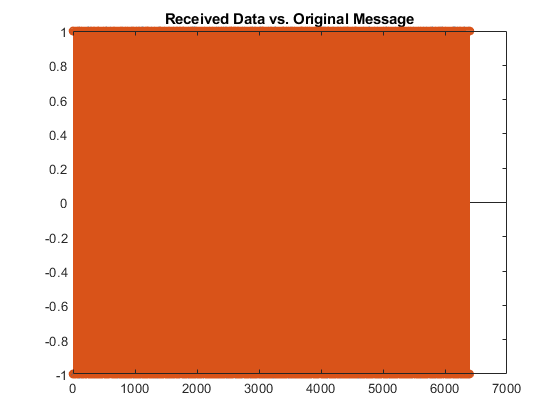


figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Error = abs(sum(diff)/(length(diff))) *100

Error = 49.4219

sps =2

sps = 2

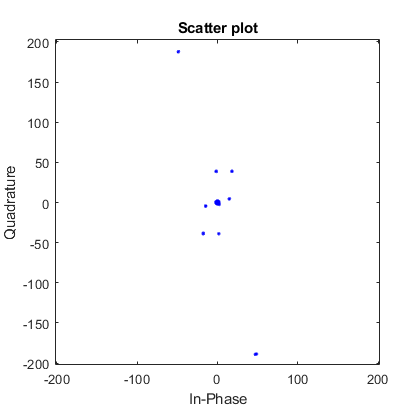

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',sps, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
scatterplot(Y_m,16)

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end


Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);